# Problem 1

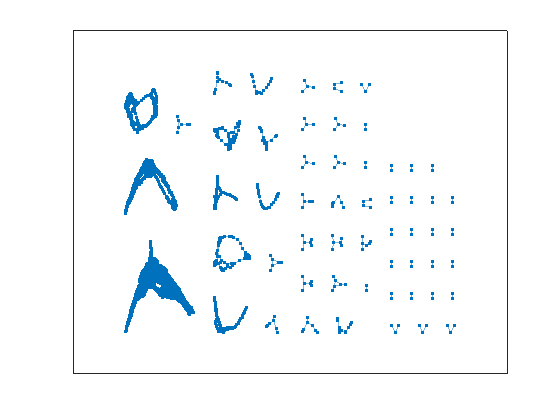

% Loading Data

data = load("usroads.mat");

G = graph(data.Problem.A);
plot(G)

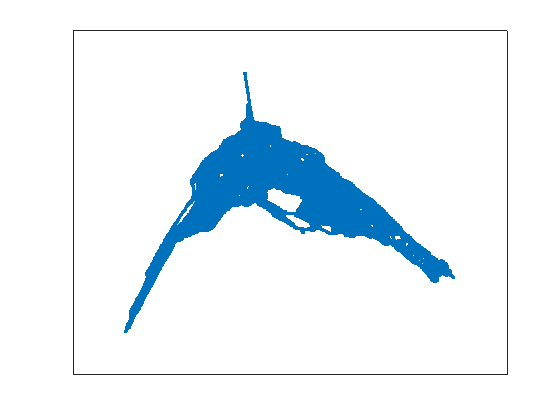


comps = conncomp(G);

SG = subgraph(G, comps==28);
plot(SG)

## Problem 1.1

A_SG = adjacency(SG);
A_SG = [0 0 0 0 0 0 0 0 1 0 0 0 0 0 0;
0 0 0 0 0 1 1 0 1 0 0 0 0 0 0;
0 0 0 0 1 0 0 0 1 0 0 0 0 0 0;
0 0 0 0 0 0 1 0 0 0 1 0 0 1 0;
0 0 1 0 0 0 0 0 0 0 1 0 0 1 0;
0 1 0 0 0 0 0 0 0 0 0 0 0 0 0;
0 1 0 1 0 0 0 1 0 0 0 0 0 0 1;
0 0 0 0 0 0 1 0 0 0 0 0 0 0 0;
1 1 1 0 0 0 0 0 0 0 0 1 1 0 1;
0 0 0 0 0 0 0 0 0 0 0 0 1 0 0;
0 0 0 1 1 0 0 0 0 0 0 0 0 1 0;
0 0 0 0 0 0 0 0 1 0 0 0 0 1 1;
0 0 0 0 0 0 0 0 1 1 0 0 0 0 0;
0 0 0 1 1 0 0 0 0 0 1 1 0 0 0;
0 0 0 0 0 0 1 0 1 0 0 1 0 0 0]

A_SG =      0     0     0     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     1     1     0     1     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     1     0     0     1     0
     0     0     1     0     0     0     0     0     0     0     1     0     0     1     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     1     0     0     0     1     0     0     0     0     0     0     1
     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0
     1     1     1     0     0     0     0     0     0     0     0     1     1     0     1
     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0



A_SG = A_SG./sum(A_SG)

A_SG =          0         0         0         0         0         0         0         0    0.1667         0         0         0         0         0         0
         0         0         0         0         0    1.0000    0.2500         0    0.1667         0         0         0         0         0         0
         0         0         0         0    0.3333         0         0         0    0.1667         0         0         0         0         0         0
         0         0         0         0         0         0    0.2500         0         0         0    0.3333         0         0    0.2500         0
         0         0    0.5000         0         0         0         0         0         0         0    0.3333         0         0    0.2500         0
         0    0.3333         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.3333         0    0.3333         0         0         0    1.0000       

## Problem 1.2

% Find the page rank of this network using power iteration.

% Need to find the page rank iteratively since the complete matrix is
% large...
alpha = 0.5;
k = 5;
n = length(A_SG);
%Make a column vector of 1's normalized to n
v = eye(n, 1) / n;

partial = alpha*A_SG*v;

v_sum = v + partial;

for i = 2:k
    partial = alpha*A_SG*partial;
    v_sum = v_sum + partial;
end

x = (1- alpha)*v_sum;
x

x =     0.0349
    0.0017
    0.0016
    0.0001
    0.0005
    0.0003
    0.0006
    0.0001
    0.0192
    0.0004


pr = ((1-alpha)/n)*pinv(eye(n,n) - alpha*A_SG)*eye(n,1)

pr =     0.0349
    0.0019
    0.0017
    0.0002
    0.0005
    0.0003
    0.0007
    0.0001
    0.0193
    0.0005


norm(pr - x, 1)

ans = 0.0010

2*alpha^k

ans = 0.0625

% Sensitivity
%todo: Ask professor about sensitivity

%S = S_p*mpower(S_p, -2)*v
